# Opgave 1:

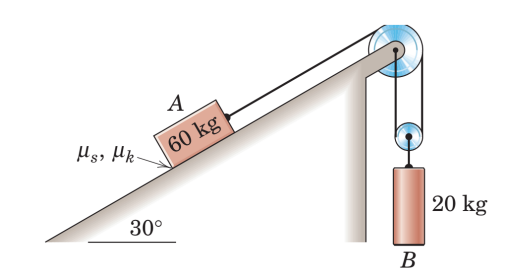

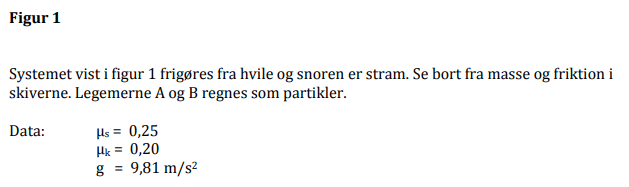

## A) Optegn FBD for legeme A & B:

Er tegnet.. GoPro oplader.

## B) Begrund hvorfor legeme A bevæger sig:

Legemet A bevæger sig nedad bakken grundet objektets vægt bidrag overgår den snorkræft overført fra B eget bidrag.

Bevis:

Vi starter med at liste alle vores kendte størrelser:

- Massen af objektet A: $m_A = 60 kg$

- Den statiske friktionskoefficient: $\mu_s = 0.25$

- Den kinetiske friktionskoefficient: $\mu_k = 0.2$

- Tyngdeaccelerationen: $g = 9.81 \frac{m}{s^2}$

- Massen af objektet B: $m_B = 20 kg$

- Hældningen på bakken hvor objektet A er placeret: $\theta = 30\degree $

Herfra vælger vi ud fra vores FDB at lægge vores koordinat system, så det følger vores bakke.

Når det er gjort skal det testes om objektet A overgår den statiske friktionskoefficient:

- 
$$F_{max} = N \cdot \mu_s$$


Vores modstående kræft $N$ er fundet gennem summeringen af kræfterne i y-retningen:

- 
$$\sum F_y = 0 : N - m_A \cdot g \cdot sin(30\degree ) = 0 \rightarrow N = 60kg \cdot 9.81 \frac{m}{s^2} \cdot sin(30\degree ) = 509.7426 N$$


Hvilket gør, at vores $F_{max}$ har størrelsen: $509.7426 N \cdot 0.2 = 127.4356 N$

Kraften som skal overgå $F_{max}$ er retningskræften, der i dette tilfælde er vores objekts kræfter i x-retningen:

- 
$$\sum F_x = 0: F - m_A \cdot g \cdot cos(\theta) = 0 \rightarrow F = 60kg \cdot 9.81 \frac{m}{s^2} \cdot cos(30\degree ) = 294.3 N$$


Da F (196.2 N) > $F_{max}$ (127.4356 N) så har vi bevægelse.

m_A = 60;
m_B = 20;
g = 9.81;
theta = deg2rad(30);
mu_s = 0.25;
mu_k = 0.2;

% Den modstående kræft:
N = m_A * g * cos(theta)

N = 509.7426

F_max = N * mu_s 

F_max = 127.4356

F =  m_A * g * sin(theta) - (m_B*g)/2

F = 196.2000

## C) Hvilken sammenhæng er der mellem accelertionerne af A & B?

Grundet udvekslingen i trissen vil bevægelsen i B være dobbelt så stor som A, hvoraf accelerationen vil medfølge.

Dette betyder:

- 
$$ a_A =2 \cdot a_B$$


## D) Beregn accelerationerne $a_A \, \& \, a_B$ samt snorkraften T.

Da der ikke er en acceleration i y-retningen, fordi vores koordinat system er lagt mod x-retningen, så er vores objekt B også flyttet i x-retningen.

Dette giver os:


$$\sum F_x = m \cdot a: T + \mu_k \cdot N - m_A \cdot g \cdot sin(\theta) = m_A \cdot 2 \cdot a$$



$$\sum T = m \cdot a : -2 \cdot T + F = m_B \cdot a$$


syms a T;
eq1 = T + mu_k * N - m_A *g * sin(theta) == m_A * 2*a;
eq2 = -2 * T + F == m_B * a;
eq3 = vpasolve([eq1 eq2], [T a]);
eq3.T

$$ans = 105.35011457434583585032109672634$$

eq3.a

$$ans = -0.7250114574345835850321096726335$$

Hvilket gør at $a_B$ er ligmed: $a_B = \frac{a_A}{2} = -0.7854 \frac{m}{s^2}$.

Og $a_A$ er ligmed: $a_A = 2\cdot a_B = -1.45 \frac{m}{s^2}$

## E) Beregn flytningen $s_A$ og hastigheden $v_A$ 10 sekunder efterfrigørelse.

Flytningen $s_A$ kan findes gennem den generelle flytningsformel: 

- 
$$s = s_{0} + v_{0}*t+\frac{1}{2}*a*t^2 \rightarrow 0 +0 * 10 + \frac{1}{2} \cdot (2 \cdot -0.7854 \frac{m}{s^2}) \cdot 10^2 = -72.501 m$$


Hvoraf hastigheden for objekt A kan bestemmes ved:

- 
$$v = \frac{ds}{dt}=\dot{s} = v_0 + a * t \rightarrow v_A = 0 + (2 \cdot -0.7854 \frac{m}{s^2}) \cdot 10^2 = -14.5 \frac{m}{s}$$


t = 10;
s = 0.5 * 2*eq3.a * t^2

$$s = -72.50114574345835850321096726335$$


v = 2 * eq3.a * t

$$v = -14.50022914869167170064219345267$$

# Opgave 2:

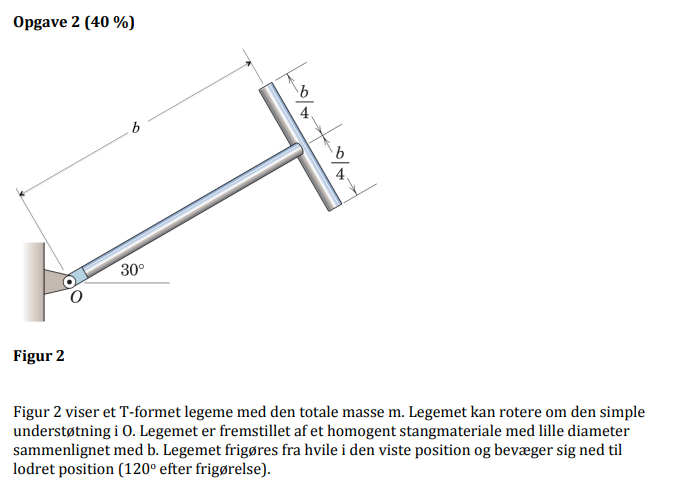

## A) Beregn afstanden $r_G$ fra O til massemidtpunktet G og legemets masseinertimoment $I_O$ om O

Det er muligt at finde $r_G$ ved følgende formel, der tager udgangspunkt i afstanden til hver form som figuren består af centroide placering, samt massen tilknyttet formen.

Før formlen præsenteres skal et udtryk for massen oprettes. Det er oplyst at figuren har den samlede masse m.

Dette betyder, at for den samlede lægnde af figuren:

- 
$$\frac{b}{4} + \frac{b}{4} + b = m \equiv 1.5b = m \rightarrow b = \frac{m}{1.5}$$
 

Med et udtryk for massen præsenteres vores afstands formel til massemidtpunktet:

- 
$$\frac{\sum^{i}_{n = antal \, former} (m_i \cdot x_i)}{\sum m} =

\frac{\frac{m}{1.5} \cdot \frac{b}{2} + (\frac{ \frac{m}{1.5} }{2}) \cdot b}{\frac{m}{1.5} + (\frac{ \frac{m}{1.5} }{2})} = \frac{2b}{3}$$


clear all;
syms m b g omega;
r_G = (2/3)*(b/2) + (1/3)*b

$$r\_G = \frac{2\,b}{3}$$

Legemets masseinertimoment om O kan findes ved at summere masse inertimomenterne i forhold til O:

- 
$$\sum I_O = I_{Slenderrod_O} + I_{Slenderrod_b}$$


Hvoraf..

-  
$$I_{Slenderrod_O} = \frac{1}{3} \cdot m \cdot L^2 \rightarrow \frac{1}{3} \cdot \frac{1m}{1.5} \cdot b^2$$


- 
$$I_{Slenderrod_b} = \frac{1}{12} \cdot m \cdot L^2 \rightarrow  \frac{1}{12} \cdot \frac{1m}{3} \cdot ((\frac{b}{2}) + b^2)$$


Hvilket gør at $I_O = \frac{9 \cdot b^2 \cdot m}{16}$

I_O = (1/3) * ((2*m)/3) * b^2 + (m/3) * ((1/12) *(b/2)^2 + b^2) 

$$I\_O = \frac{9\,b^{2}\,m}{16}$$

## B) Beregn legemets vinkelhastighed i lodret position

Legemets vinkelhastighed kan findes arbejdslinginen:

- 
$$T_1 + U_{1-2} = T_2$$


Her vil vores første kinetiske arbejde være = 0.

Hvoraf arbejdet fra 1 -> 2 vilæ være:

- 
$$U_{1-2} = m \cdot g \cdot r_G \cdot sin(30\degree  + 90\degree )$$


Hvortil det endelig kinetiske arbejde er:

- 
$$T_2 = \frac{1}{2} \cdot \frac{9 \cdot b^2 \cdot m}{16} \cdot \omega^2$$


Hvorved  den ønskede vinkelhastighed bliver:

- 
$$\omega = \sqrt{\frac{m \cdot g \cdot r_G \cdot sin(30\degree  + 90\degree )}{\frac{1}{2} \cdot \frac{9 \cdot b^2 \cdot m}{16}}} =

- \frac{1.5387 \cdot \sqrt{g}}{\sqrt b}$$


A = vpasolve(m *g * r_G * (sin(deg2rad(30) + sin(pi/2))) == (0.5) * I_O * omega^2,omega)

$$A = \left(\begin{array}{c} -\frac{1.5387432311589717981763763669496\,\sqrt{g}}{\sqrt{b}}\\ \frac{1.5387432311589717981763763669496\,\sqrt{g}}{\sqrt{b}} \end{array}\right)$$

## C) Optegn FDB & KD i lodret position.

## D) Beregn reaktionerne i O.

Da vores objekt nu vender lodret nedad, så vil vores reaktioner mod O være:

- 
$$\sum F_y = m \cdot a_y: O_y - m \cdot g = m \cdot r_G \cdot \omega^2 \rightarrow O_y = m \cdot r_G \cdot \omega^2 + m \cdot g$$


# Opgave 3:

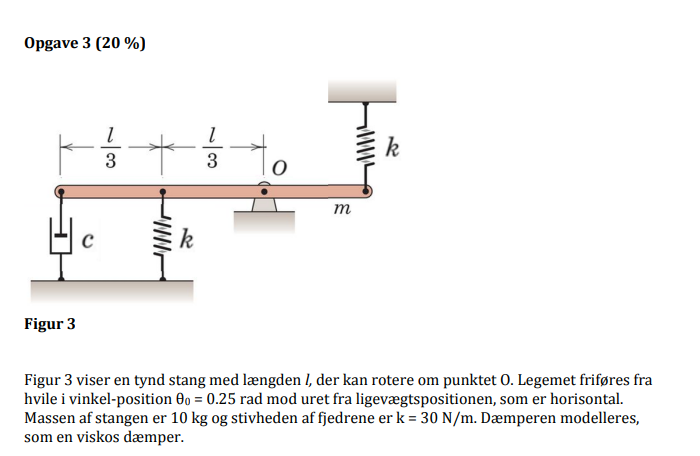

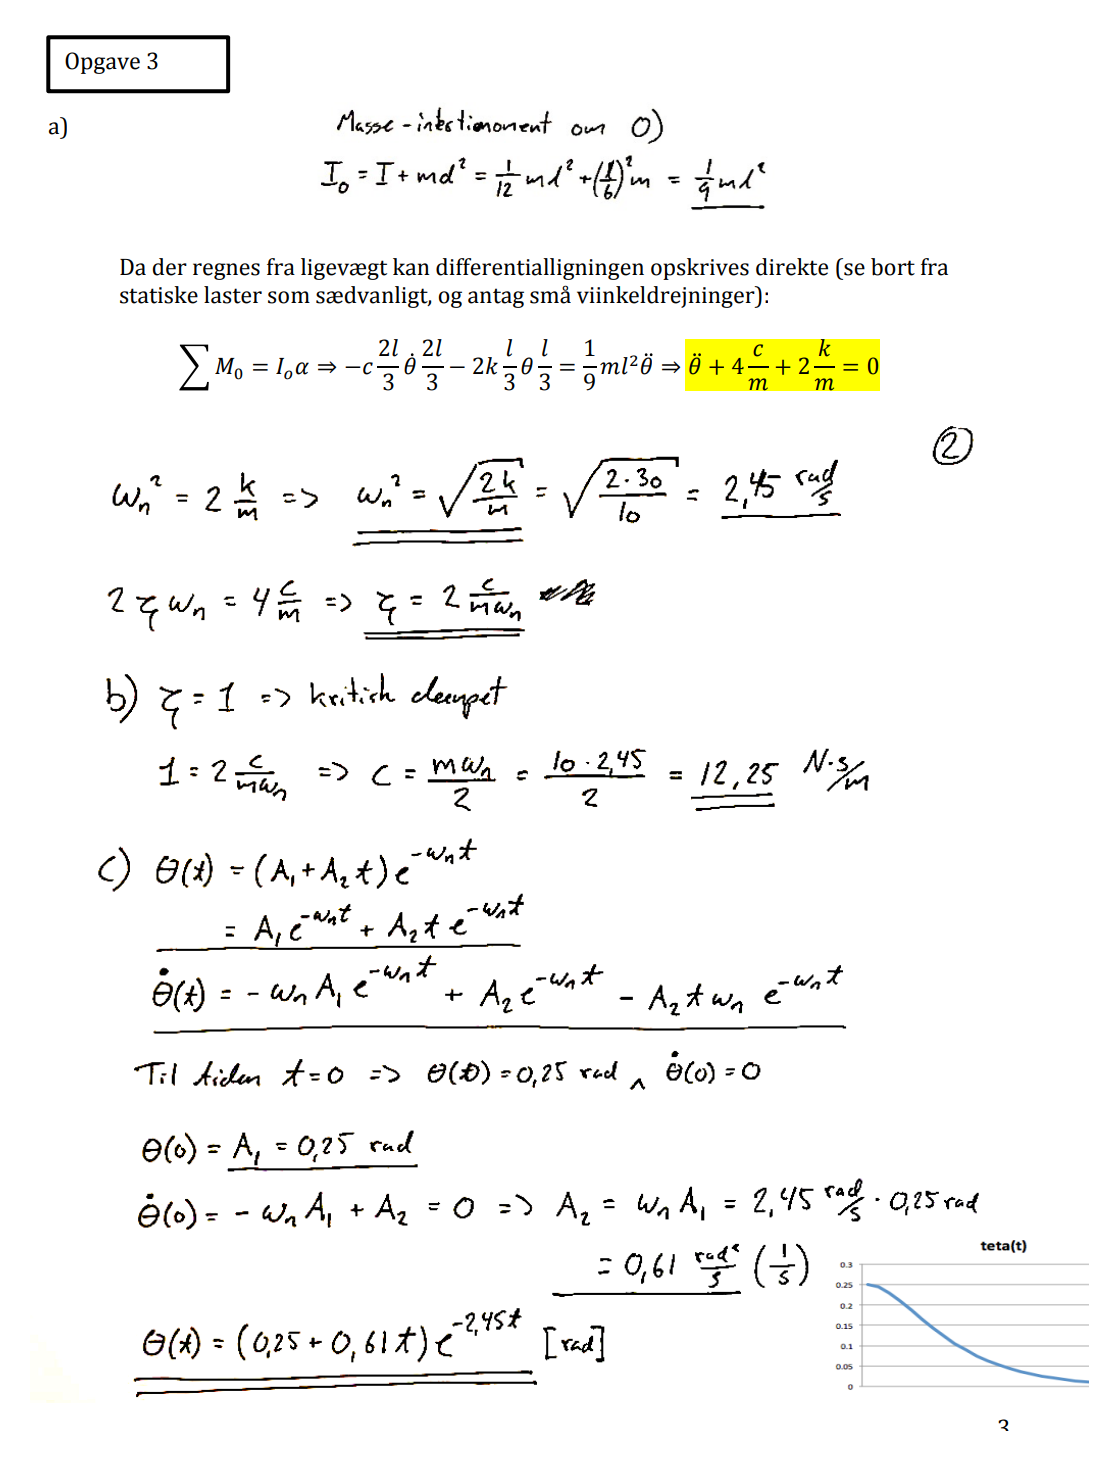 

## A) Opskriv et udtryk for systemets cylindriske egenfrekvens $\omega_n$ og dæmpningsforholdet $\zeta$. (Antag små vinkeldrejninger)

- 
$$\omega = \sqrt{\frac{k}{m}} \rightarrow \omega_n = \sqrt{\frac{2 * 30}{10}} = 2.45 \frac{rads}{s}$$


- 
$$\zeta = \frac{c}{2 \cdot m \cdot \omega_n}$$


clear all;
k = 30;
m = 10;
omega_n = sqrt(2*k/m)

## B) Bestem dæmpningskoefficienten $c$ så systemet er kritisk dæmpet.

Hvis systemet skal være kritisk dæmpet, så skal $\zeta =1$

Så vi løser en ligning med en 1 ubekendt:

- 
$$\zeta = \frac{c}{2 \cdot m \cdot \omega_n} 
\rightarrow 
1 = \frac{c}{2 * 10 * 2.45} 

\rightarrow 
c = 48.99 N \cdot \frac{s}{m}$$


syms c;
vpasolve(1 == c/(2*m*omega_n),c)

omega_n = 2.4495

$$ans = 48.989794855663561963945681494118$$

## C) Opskriv en funktion for vinkeldrejningen $\theta(t)$, hvor $t$ er tiden fra frigørelsen og skitser funktionen.